Just setting up data points

theta_full = pi/180:pi/180:2*pi;
mu = 54*pi/180;
sigma = 10*pi/180;
data_fab = normpdf(theta_full,mu,sigma);

rawdata1 = data_fab ;%+ circshift(data_fab', 180)';
rawdata2 = circshift(rawdata1', 30)';
rawdata3 = circshift(rawdata1', 45)';
rawdata4 = circshift(rawdata1', 50)';

data_point1 = data_point;
data_point2 = data_point;
data_point3 = data_point;
data_point4 = data_point;

data_point1.intensity_data = rawdata1;
data_point2.intensity_data = rawdata2;
data_point3.intensity_data = rawdata3;
data_point4.intensity_data = rawdata4;

data_point1 = data_point1.Normalize;
data_point1 = data_point1.GenerateFourier(14);
data_point2 = data_point2.Normalize;
data_point2 = data_point2.GenerateFourier(14);
data_point3 = data_point3.Normalize;
data_point3 = data_point3.GenerateFourier(14);
data_point4 = data_point4.Normalize;
data_point4 = data_point4.GenerateFourier(14);


data_point1.x = 0;
data_point1.y = 0;

data_point2.x = 1;
data_point2.y = 0;

data_point3.x = 0;
data_point3.y = 1;

data_point4.x = 1;
data_point4.y = 1;

Where to interpolate at

x_prime = 0.25;
y_prime = 0.25;

**Method one: Using bilinear interpolation**

data_pointI = data_point; % data point - registered data point
data_pointI.x = x_prime;
data_pointI.y = y_prime;
data_pointI.an = [];
data_pointI.bn = [];
 
for i=1:length(data_point1.an)
    a = u(data_pointI.x,data_pointI.y, data_point1.an(i),data_point2.an(i),data_point3.an(i),data_point4.an(i));
    b = u(data_pointI.x,data_pointI.y, data_point1.bn(i),data_point2.bn(i),data_point3.bn(i),data_point4.bn(i));
    
    data_pointI.an = [data_pointI.an a];
    data_pointI.bn = [data_pointI.bn b];
end

fit1 = evalFourierRad(data_point1.an, data_point1.bn, 1, theta_full);
fit2 = evalFourierRad(data_point2.an, data_point2.bn, 1, theta_full);
fit3 = evalFourierRad(data_point3.an, data_point3.bn, 1, theta_full);
fit4 = evalFourierRad(data_point4.an, data_point4.bn, 1, theta_full);
fitI = evalFourierRad(data_pointI.an, data_pointI.bn, 1, theta_full);

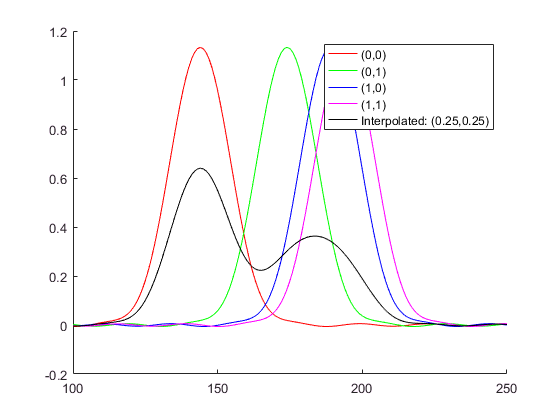

figure
hold on 
plot(100:250, fit1(100:250), 'r');
plot(100:250, fit2(100:250), 'g');
plot(100:250, fit3(100:250), 'b');
plot(100:250, fit4(100:250), 'm');
plot(100:250, fitI(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime), 'location','eastoutside');
hold off

**Method 2: Using the gridded interpolant method**

data_points1 = [data_point1, data_point3,data_point2,data_point4];

x = [data_points1(:).x];
y = [data_points1(:).y];
step_size =  data_points1(2).x - data_points1(1).x;
[X1, X2] = ndgrid(0.0:1 , 0.0:1);

Interpolation step to find values for each coefficient

an_prime = [];
for i = 1:7 % for each coeff
   f = [];
   for j = 1:4 % for each data_point
       f(j) = data_points1(j).an(i);
   end

   f_r = reshape(f, [2,2]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   an_prime(i) = F_interp(x_prime, y_prime);
end

bn_prime = [];
for i = 1:(7) % for each coeff
   f = [];
   for j = 1:4 % for each data_point
       f(j) = data_points1(j).bn(i);
   end

   f_r = reshape(f, [2,2]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   bn_prime(i) = F_interp(x_prime, y_prime);
end

d_int = data_point;
d_int.an = an_prime;
d_int.bn = bn_prime;
d_int.odf = evalFourier(an_prime, bn_prime, 1, 1:360);

figure
hold on 
plot(100:250, fit1(100:250));
plot(100:250, fit2(100:250));
plot(100:250, fit3(100:250));
plot(100:250, fit4(100:250));
plot(100:250, d_int.odf(100:250));
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off